# TRI Data File

**Author: Nina Matthews**

**Project: Masters Dissertation - Hierarchical portfolio stress-testing with flexible probabilities**

**Last edit: 27/07/2023**

**Supervisor: A/Prof. Tim Gebbie**

**Resources Used: **The MathWorks, Inc. (2019) 

#### **Needed Data: **

#### ASSET Px_Last

"DATA-PROCESSED-SIG-PX_LAST-M-TTABLE-20000229-20230228.mat"

#### Signal Px_Last

"DATA-PROCESSED-SIG-PX_LAST-M-TTABLE-20000229-20230228.mat"

## **Purpose**

*****

*****

*****

## **1. Environment Setup **

**Clear Env and Plots**

clc % clear command window
close all %clear all figs
clear % clears workspace

**Source Directories **

Set path for processed data

% Add Data source directory
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'));

**Export Directories**

Set Image export path:

% use your default user path to create the filename and path
exportName = '';
imageExportpath = fullfile('/Users/Ninamatthews/Desktop/MASTERS/Images/Data Manipulation/',exportName);

Set Output data EXPORT path

dataExportpath = fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/', exportName);

## 2. Load Test Data: ASSET Log Dif Returns & Sig Data

**Set Directories & Load Data**

Load Processed Signal and Asset Class data

% use your default user path to create the filename and path
addpath(fullfile(userpath,'/STA5000W DISSERTATION Code/Data/PROCESSED/'))
load 'DATA-PROCESSED-SIG-PX_LAST-M-TTABLE-20000229-20230228.mat';
load 'DATA-PROCESSED-ASSETCL-PX_LAST-M-TTABLE-20070630-20230228.mat';

% Extract the market and cash columns
columnsToExtract = {'JIBA3M_Index','JALSHTR_Index'};
Mrkt_CashTT = SIG_aligned_dataTable(:, columnsToExtract);
% Combine the timetables
BALFUN_TT = synchronize(ASSETCL_TableFilled,Mrkt_CashTT);

Here we see that it's only missing data at the start and not inbetween. 

Create plot names (excludes the underscore)

% rename the variables with underscores instead of spaces
ASSETCL_PlotNames = strrep(BALFUN_TT.Properties.VariableNames, '_', ' ');
% remove the 'TR' the variables with underscores instead of spaces
ASSETCL_PlotNames = strrep(ASSETCL_PlotNames, 'TR', '');

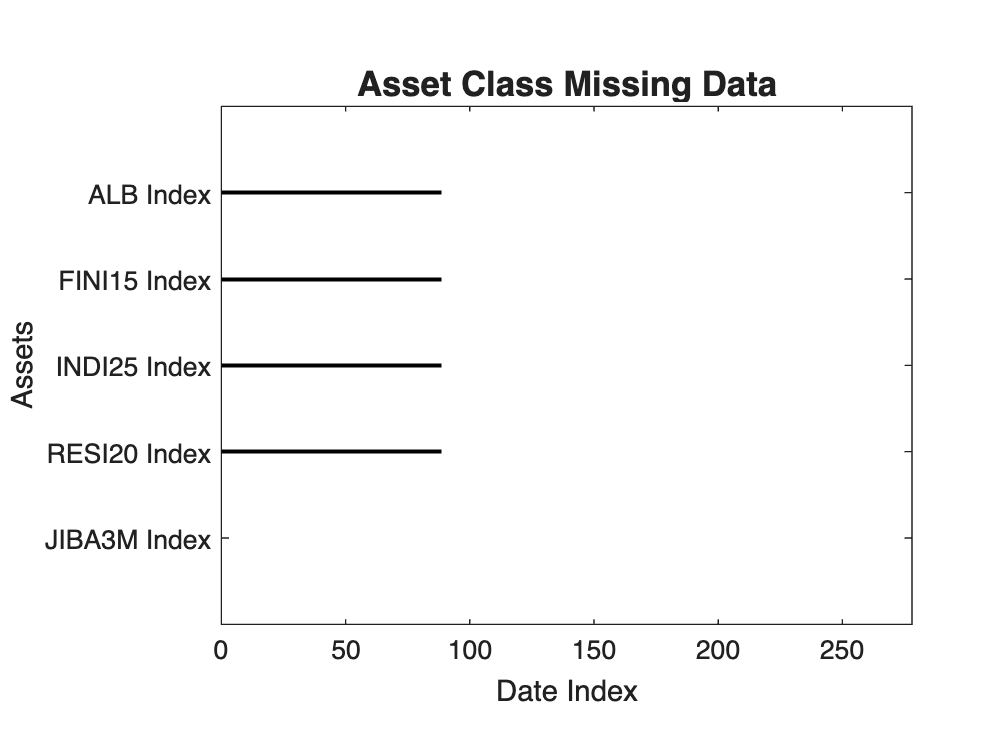

% missing data to plot in array
tickers = BALFUN_TT.Properties.VariableNames;
na_array = transpose(isnan(table2array(BALFUN_TT(:,1:5))));
ax = axes;

spy(na_array, 'black-',5);
set(gca,'ytick',1:5,'yticklabel',ASSETCL_PlotNames);
pbaspect([8 6 1]);
ylabel("Assets");
xlabel("Date Index");
title("Asset Class Missing Data",'FontSize', 13);

BalancedF_NAplot = gca;
%  close all

**Export NA Data plot**

% exportName = 'BALF_NAdata_plot.pdf';
% exportgraphics(BalancedF_NAplot,fullfile(imageExportpath,exportName),'Resolution',300);

**Remove NA:** 

We currently have 23 yrs of data, however, 15 yrs of historical data should suffice, therefore we can drop the dates prior to the initial existance of all indices:

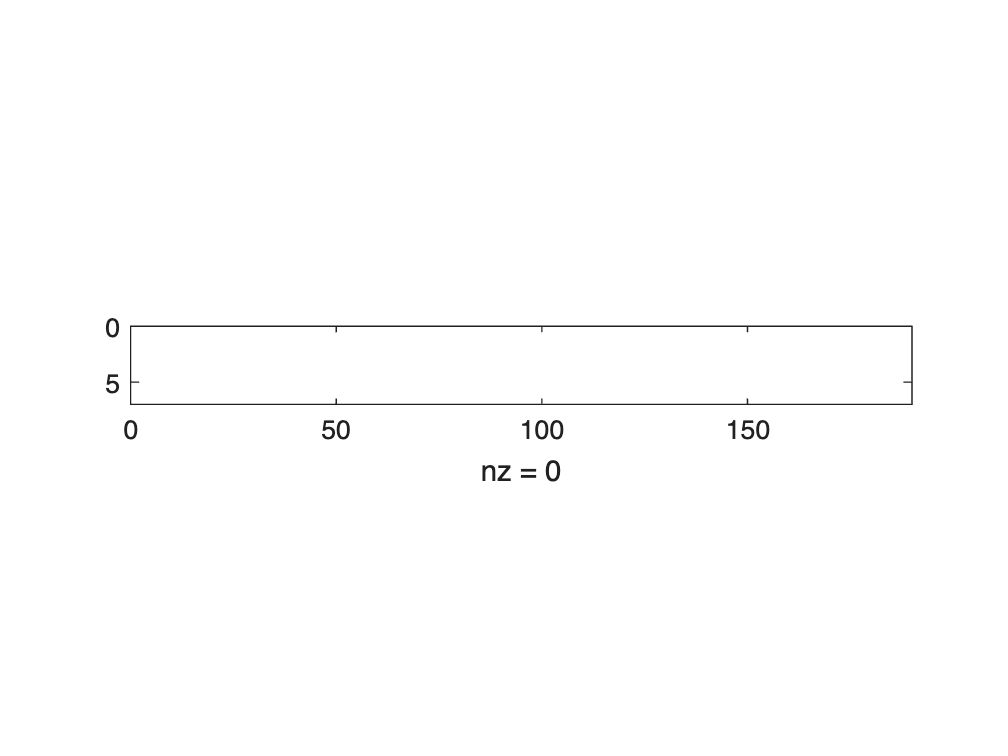

[countNans,idx] = max(sum(isnan(BALFUN_TT{:,:}),1));
rmmissingProxy =  BALFUN_TT.Properties.VariableNames{idx};
BALFUN_TT = rmmissing(BALFUN_TT,"DataVariables",rmmissingProxy);
spy(transpose(isnan(table2array(BALFUN_TT))))

**SAVE Processed Balanced Fund Datasets:**

% exportName = 'DATA-PROCESSED-BALFUN-PX_LAST-M-TTABLE-20070630-20230228.mat';
% save(fullfile(dataExportpath,exportName),'BALFUN_TT');

## 3. Invariant Prep

%rename the variables with underscores instead of spaces
% M_Ret_TT_PlotNames = strrep(BALFUN_TT.Properties.VariableNames, '_', ' ');
% % remove the 'TR' the variables with underscores instead of spaces
% M_Ret_TT_PlotNames = strrep(M_Ret_TT_PlotNames, 'TR', '');

3.1 **Normalize ** the TRI series to have the first index value of each asset equal to  

This creates a comparative wealth series for each asset over the time period.

% % Divide each element in each column of x by the first element of that column
% BALFUN_normalised_array = table2array(BALFUN_TT) ./ table2array(repmat(BALFUN_TT(1,:),height(BALFUN_TT),1));
% 
% % Convert the normalised array back to a timetable with the same timestamps as x
% BALFUN_normalised = array2timetable(BALFUN_normalised_array, 'RowTimes', BALFUN_TT.Dates);
% 
% % Copy the column names from x to x_normalised
% BALFUN_normalised.Properties.VariableNames = BALFUN_TT.Properties.VariableNames;

% assetnames = BALFUN_normalised.Properties.VariableNames;
% % Plot all asset normalised TRIs on a single plot
% plot(BALFUN_normalised.Time, table2array(BALFUN_normalised), 'LineWidth', 1.5);
% ylabel("Normalised TRIs");
% xlabel("Time");
% title("Monthly Normalised Wealth Series From TRIs",'FontSize', 13);
% % include the legend
% legend(M_Ret_TT_PlotNames,'Location',"northwest",'FontSize', 12);
% BALFUN_norm_plot = gca;
% hold off;

**Export Normalized Asset Class Wealth Series From TRIs Data plot**

% exportName = 'BALFUN_norm_plot.pdf';
% exportgraphics(BALFUN_norm_plot,fullfile(imageExportpath,exportName),'Resolution',300);

### 3.1 *** Remove JIBA3M as a forward rate needs to be calculated ***

BALFUN_TT_array = table2array(BALFUN_TT);
JIBA3M = BALFUN_TT.JIBA3M_Index;
BALFUN_TT = removevars(BALFUN_TT, 'JIBA3M_Index');

BALFUN_TT.Properties.Description = 'Monthly Sampled Simple Returns';

BALFUN_TT.Properties.Description 

ans = 'Monthly Sampled Simple Returns'

### 3.2 JIBA Monthly Rate 

JIBA3M is quoted as an annualised values, therefore we first need to convert it to Quarterly as its a 3 month instrument before converting it to monthly to get cash returns proxy

$\textrm{CI}={\left(1+r\right)}^{\frac{1}{N}} -1,$ where CI is the compounded interest, r is the rate of returns and N is the frequency of interest compounding.

[m,~]=size(BALFUN_TT); % size of TT
% Convert percentage reported value to decimal
JIBA3M_deci = JIBA3M/100;
% Storage for Quarterly and Monthly values
JIBA_q = zeros(m, 1);
JIBA_m = zeros(m, 1);

for t=1:m-1
    % 1. Compute QUARTERLY rate from Annual reported rate
    JIBA_q(t) = ((1+JIBA3M_deci(t,:))^(1/4))-1;
    % 2. Compute MONTHLY expected returns from quarterly
    JIBA_m(t+1) = (((1+JIBA_q(t,:))^(1/3))-1);
end

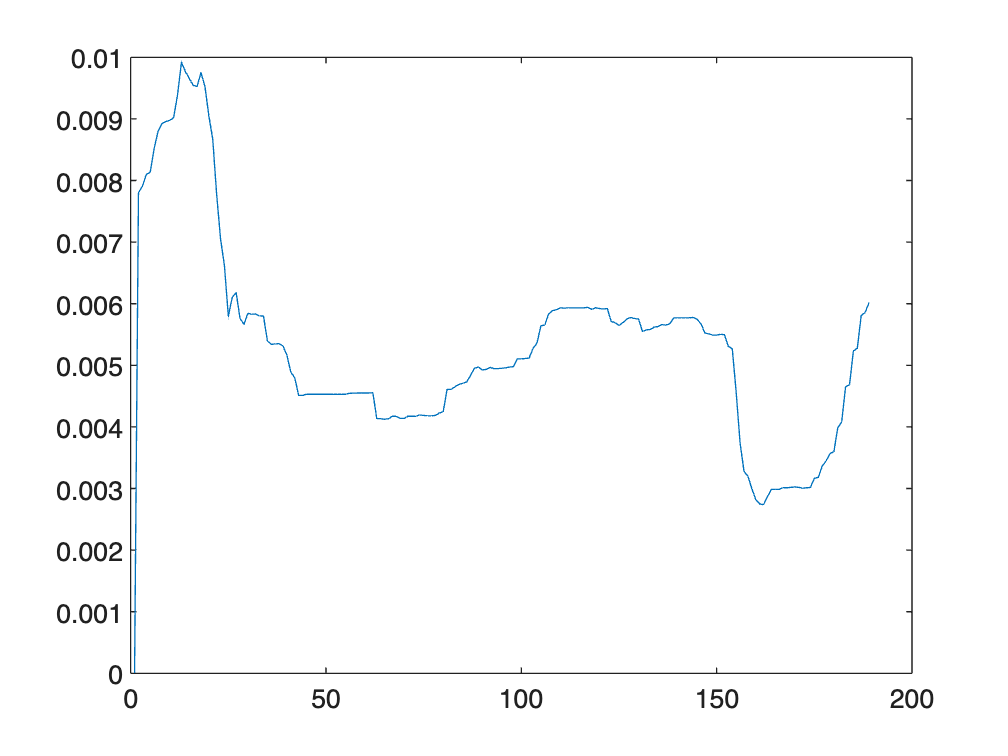

plot(JIBA_m)

### 3.3 Simple returns for all none cash assets

%***************************************************************************
% Get the number of columns in the timetable
[m,n]=size(BALFUN_TT); % size of TT
% Returns (include zero or nan for the start)
Ret = zeros(m,1);

% Preallocate arrays for monthly returns and geometric return series
% M_Ret_TT = timetable('RowTimes', BALFUN_TT.Dates(1:end));
M_Ret_TT = timetable('RowTimes', BALFUN_TT.Dates);

for col = 1:n
 
    %%% APPROACH 1
    % Get the price data (column) for the current variable
    prices = BALFUN_TT{:, col};
    for t=1:m-1
        % 1. Computer returns (asset returns)
        Ret(t+1,:) = (prices(t+1,:)./prices(t,:))-1;
    end

    M_Ret_TT.(BALFUN_TT.Properties.VariableNames{col}) = Ret;
end

#### Add back the JIBAR interest rate to returns table

%%%%%% Add JIBA monthly rate to M_Ret_TT as cash proxy  %%%%%%
M_Ret_TT.Cash = JIBA_m;
%% JIBA_Ret here is judt for comparison amd not used going forward %%%%
% Add original JIBA back for comparison
JIBA_Ret = zeros(m,1);

for t=1:m-1
        % 1. Computer returns (asset returns)
        JIBA_Ret(t+1,:) = (JIBA3M(t+1,:)./JIBA3M(t,:))-1;
end
M_Ret_TT.JIBA3M = JIBA_Ret;

Remove 1st observation as it is equaly to zero

M_Ret_TT = M_Ret_TT(2:end,:);


### 3.4 Geometrically Compounded Return Series 

Calculate simple returns to use in Geometrically compounded returns

% Get the number of columns in the timetable
[m,n] = size(M_Ret_TT);
M_Ret_array =  table2array(M_Ret_TT);
% % Preallocate arrays for monthly returns and geometric return series
GRet = zeros(m, n);
GRet_TT = timetable('RowTimes', M_Ret_TT.Time);
% 
% Calculate monthly returns and geometric return series for each column
for col = 1:n
    
    % Convert the monthly returns to decimal form
    decimal_returns = M_Ret_array(:, col) + 1; 
    
    % Calculate the geometric return series for the current variable
    GRet(:, col) = cumprod(decimal_returns) - 1;
end

ans = 0

%rename the variables with underscores instead of spaces
M_Ret_TT_PlotNames = strrep(M_Ret_TT.Properties.VariableNames, '_', ' ');
% remove the 'TR' the variables with underscores instead of spaces
M_Ret_TT_PlotNames = strrep(M_Ret_TT_PlotNames, 'TR', '');

Plot Geo Returns

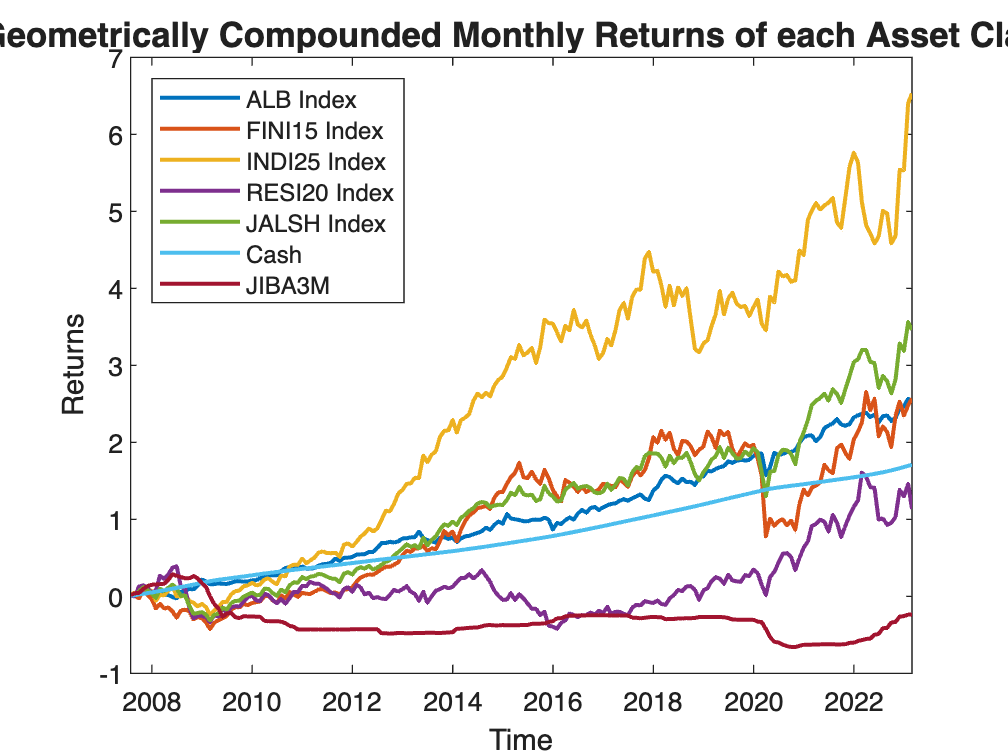

plot(GRet_TT.Time, GRet, 'LineWidth', 1.5)
ylabel("Returns")
xlabel("Time")
title("Geometrically Compounded Monthly Returns of each Asset Class",'FontSize', 13)
% include the legend
legend(M_Ret_TT_PlotNames,'Location',"northwest",'FontSize', 9);

### Plot JIBA3M vs Proxy Returns

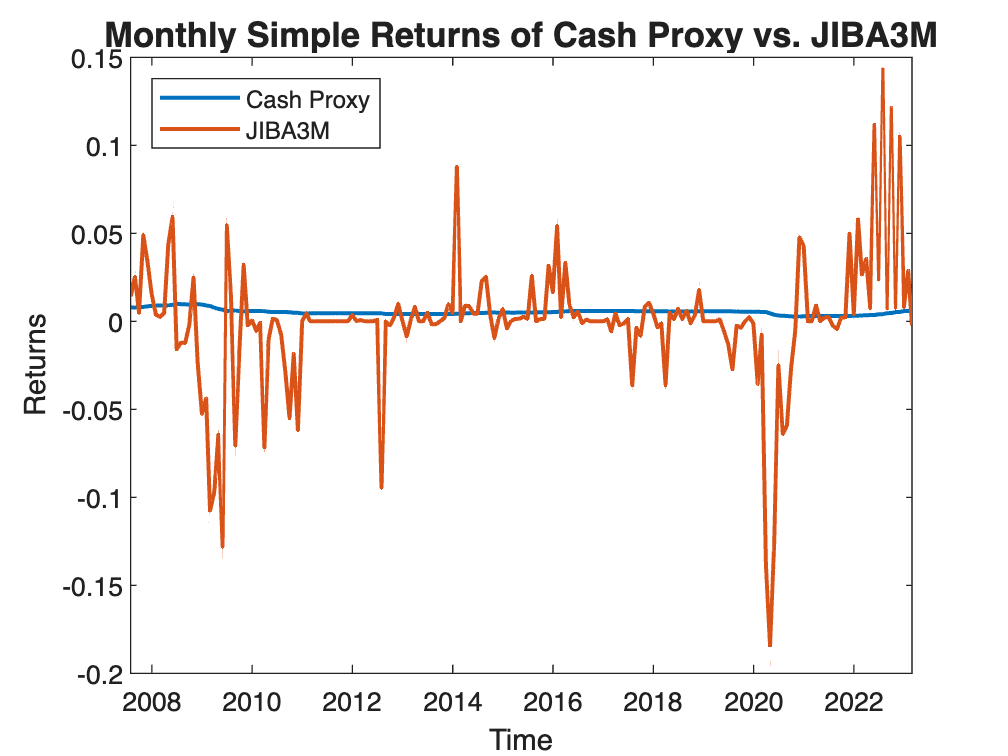

cash_JIBA = [M_Ret_TT.Cash M_Ret_TT.JIBA3M];
plot(M_Ret_TT.Time, cash_JIBA, 'LineWidth', 1.5);
ylabel("Returns")
xlabel("Time")
title("Monthly Simple Returns of Cash Proxy vs. JIBA3M",'FontSize', 13)
% include the legend
legend({'Cash Proxy', 'JIBA3M'},'Location',"northwest",'FontSize', 9);

Monthly_Cash_JIBA_Rets = gcf;

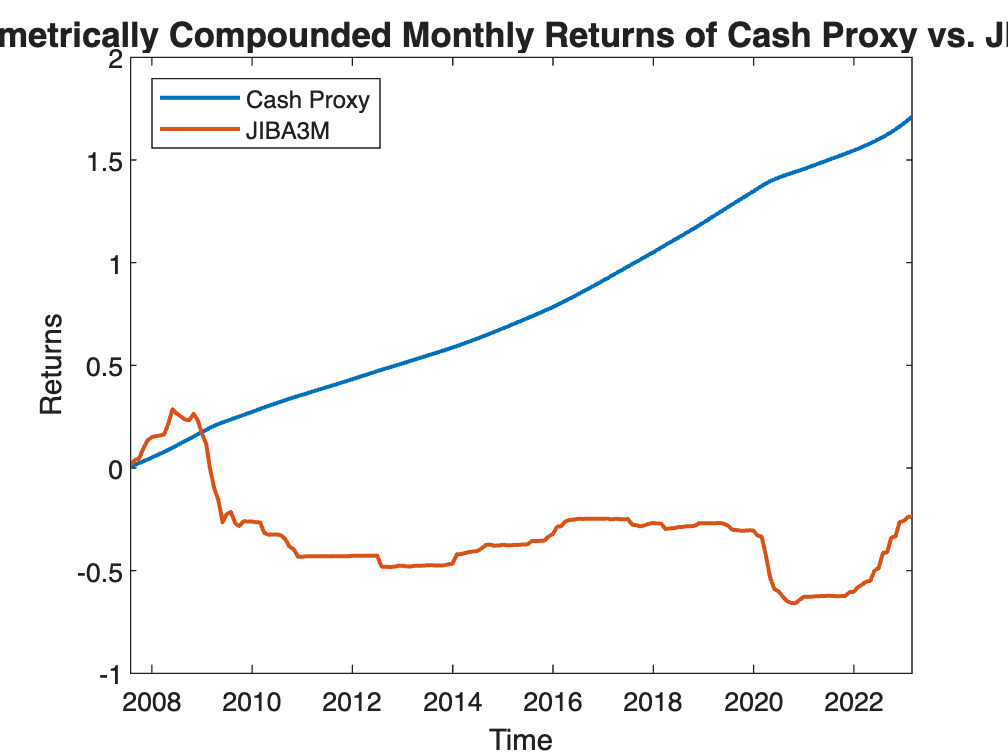

Cash_JIBA_GRETs = GRet(:,6:7);

plot(GRet_TT.Time, Cash_JIBA_GRETs, 'LineWidth', 1.5);
ylabel("Returns")
xlabel("Time")
title("Geometrically Compounded Monthly Returns of Cash Proxy vs. JIBA3M",'FontSize', 13)
% include the legend
legend({'Cash Proxy', 'JIBA3M'},'Location',"northwest",'FontSize', 9);

#### **Export Cash Returns Plot**

% exportName = 'Monthly_Cash_JIBA_Rets.pdf';
% exportgraphics(Monthly_Cash_JIBA_Rets, ...
%     fullfile(imageExportpath,exportName),'Resolution',300);

Drop JIBA3M after the above Cash and JIBA comparision:

M_Ret_TT = removevars(M_Ret_TT, 'JIBA3M');
GRet = GRet(:, 1:end-1);
M_Ret_TT_PlotNames = M_Ret_TT_PlotNames(1:6);

### 3.5 Plot Returns and key points

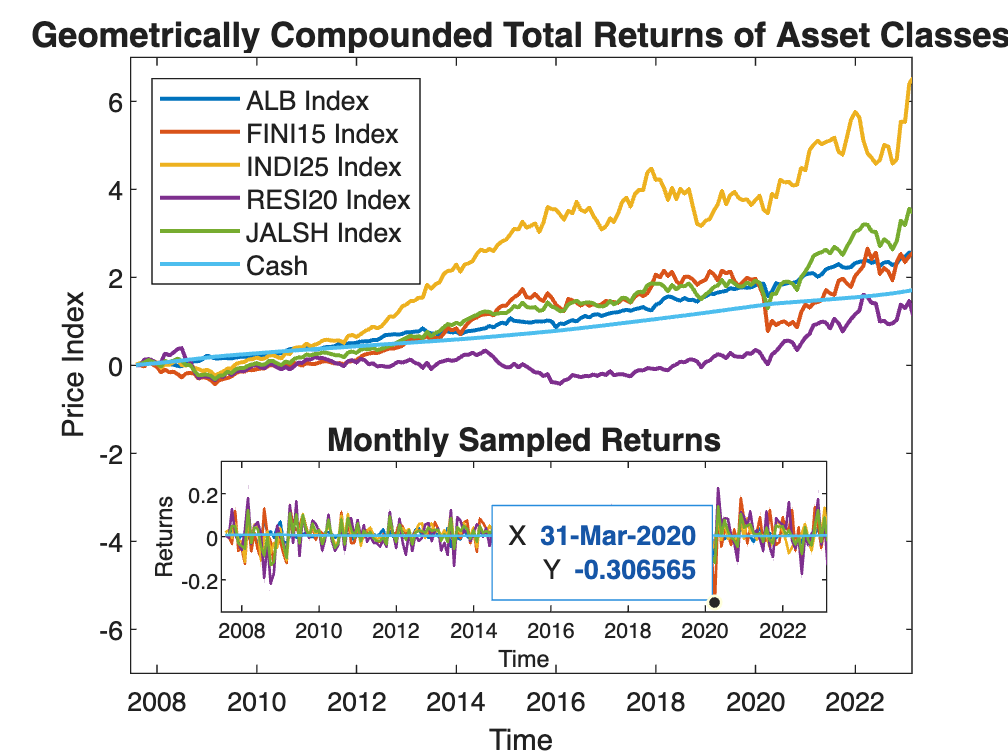

figure;
plot(GRet_TT.Time, GRet, 'LineWidth', 1.5)
ylabel("Price Index")
xlabel("Time")
xlim([datetime(2007,6,21,21,19,30)...
      datetime(2023,2,19,21,19,30)])
ylim([-7 7])

title("Geometrically Compounded Total Returns of Asset Classes",'FontSize', 13)
% include the legend
legend(M_Ret_TT_PlotNames,'Location',"northwest",'FontSize', 10);

% Create inset plot
inset_plot = axes('Position', [0.22 0.19 0.6 0.2]); % Adjust position and size as needed
% Plot Geometric Returns as inset
plot(M_Ret_TT.Time, table2array(M_Ret_TT), 'LineWidth', 1)
ylabel("Returns")
xlabel("Time")
title("Monthly Sampled Returns",'FontSize', 12)
% axes 1
xlim([datetime(2007,6,21,21,19,30)...
      datetime(2023,2,19,21,19,30)])
ylim([-0.35 0.35])

ax4 = gca;
chart = ax4.Children(5);
datatip(chart,datetime(2020,3,31,0,0,0),-0.3066);

%%% Could plot histogram of returns if wanted:
% histogram(table2array(M_Ret_TT), 'FaceColor', [0.8, 0.8, 0.8])
% title("Distribution of Returns")
% % include the legend
% xlabel("Returns")
Monthly_Ret_Assets = gcf;
hold off;

Histogram of Returns to assess distrubition: 

%% Could plot histogram of returns if wanted:
histogram(table2array(M_Ret_TT), 'FaceColor', [0.8, 0.8, 0.8])
title("Distribution of Returns")
% include the legend
xlabel("Returns")
M_Ret_TT.Properties.VariableNames
skewness(table2array(M_Ret_TT))

#### **Export Returns Plot**

% exportName = 'Monthly_Ret_Assets.pdf';
% exportgraphics(Monthly_Ret_Assets, ...
%     fullfile(imageExportpath,exportName),'Resolution',300);

#### **SAVE Returns Datasets:**

**TO DO: Use data_cleaning_001 to auto assign date range to file names (will code later)**


M_Ret_TT.Properties.Description = 'Asset class Simple RETURNS data (used as invariants). Frequency: MONTHLY. Latest Update Aug23. Original Source: Bloomberg. Intended file naming: DATA-PROCESSED-ASSETCL_INVARIANT-RETURNS-M-TTABLE-20070731-20230228.mat';
M_Ret_TT.Properties.VariableDescriptions = {'ALBI Monthly sampled returns', 'FINI Monthly sampled return',...
    'INDI Monthly sampled return','RESI Monthly sampled return', 'ALSI Monthly sampled return', 'JIBA3M forward rate as Cash Proxy Monthly sampled return'};

% % Convert the start and end dates to strings in the desired format (YYYYMMDD)
% startDateStr = datestr(ASSETCL_log_diff.Properties.StartTime, 'yyyymmdd');
% endDateStr = datestr(ASSETCL_log_diff.Properties.EndDate, 'yyyymmdd');
% 
% % Generate the file name
% fileName = sprintf('DATA-PROCESSED-INVARIANT-LOGDIFRETURNS-M-TTABLE-%s-%s.mat', startDateStr, endDateStr);
% 
% % Save the timetable object using the generated file name
% % save(fileName, 'timetableObj');

% 
exportName = 'DATA-PROCESSED-ASSETCL-RETURNS-M-TTABLE-20070731-20230228.mat';
save(fullfile(dataExportpath,exportName),'M_Ret_TT');

Asset Price Heat Map

% pairwise Pearson correlations. 
% Pvals to test correlations are significant, alpha = 5% level
% [R,PValue] = corrplot(BALFUN_TT);

AssetCorr = round(corr(BALFUN_TT_array),2);
% h = heatmap(BALFUN_PlotNames,BALFUN_PlotNames,AssetCorr, 'Colormap',winter());
% Plot the heatmap with a sliding range of colors
qq = heatmap(ASSETCL_PlotNames, ASSETCL_PlotNames, AssetCorr, 'Colormap', jet(500));
qq.Title = 'Pairwise Pearson Correlation Heatmap for Asset Price Series';

#### **Export  Plot**

% exportName = 'ASSETCL_corr_heatmap.pdf';
% exportgraphics(qq, ...
%     fullfile(imageExportpath,exportName),'Resolution',300);

## 4. Check for normal distribution of returns 

#### 3.4.1 PP Theoritical Distribution Plot

Plot PP and QQ-plots to see if log diff data is roughly normally distributed

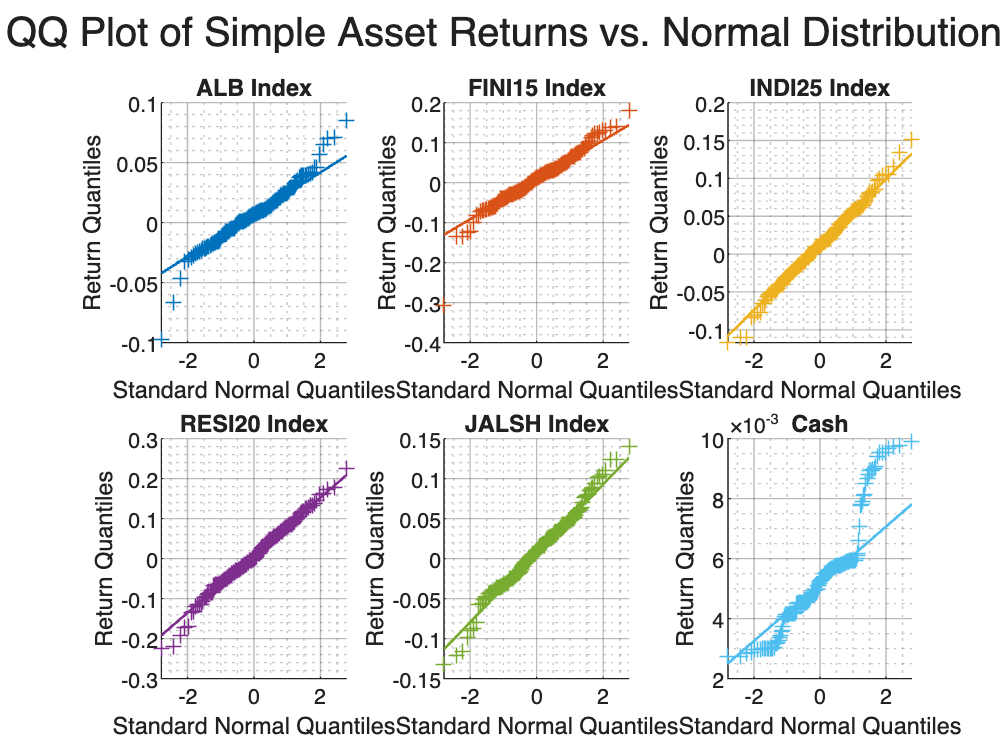

% Colour palette: Hexadecimal Colour Codes
colours = [0 0.4470 0.7410; % dark blue
          0.8500 0.3250 0.0980; % orange
          0.9290 0.6940 0.1250; % yellow
          0.4940 0.1840 0.5560; % purple
          0.4660 0.6740 0.1880; % green
          0.3010 0.7450 0.9330]; % light blue

% for k = (width(M_Ret_TT)+1):numel(qq)
%     qq(k).LineStyle = "-";
%     qq(k).LineWidth = 1;
% end

fig = figure;

% Assuming M_Ret_TT is your timetable
numCols = width(M_Ret_TT);
numRows = ceil(numCols / 3);

for col = 1:numCols
    subplot(numRows, 3, col);
    pd = fitdist(M_Ret_TT{:, col},'Normal');
    qq = qqplot(M_Ret_TT{:, col}); % 'normal' is used instead of pd
    % Use colormaps to assign different colors to each line
    qq(3).LineStyle = "-";
    qq(3).Color = [colours(col,:)];
    qq(3).LineWidth = 1;
    qq(1).MarkerEdgeColor = [colours(col,:)];
    
    ylabel("Return Quantiles")
    title(M_Ret_TT_PlotNames{col});
    grid on;

    % Adjust grid line properties
    grid(gca, 'minor');
    ax = gca;
    ax.GridAlpha = 0.3; % Set grid transparency
    ax.MinorGridAlpha = 0.25; % Set minor grid transparency
end

qq_plot_Simple_ret = fig;

sgtitle("QQ Plot of Simple Asset Returns vs. Normal Distribution");

**Export PP plot of ASSET Class log diff returns**

% exportName = 'qq_plot_Simple_ret.pdf';
% exportgraphics(qq_plot_Simple_ret, ...
%     fullfile(imageExportpath,exportName),'Resolution',300);


#### 3.4.2 PP Plot inset into QQ Plot for Returns

% Create main plot
% figure;
% qq = qqplot(table2array(M_Ret_TT));
% for k = (width(M_Ret_TT)+1):numel(qq)
%     qq(k).LineStyle = "-";
%     qq(k).LineWidth = 1;
% end
% ylabel("Quantiles of Returns");
% title("QQ Plot of Asset Returns vs. Standard Normal",'FontSize', 13);
% % legend(M_Ret_TT_PlotNames, "Location", "northwest");
% grid on; % Add grid
% 
% % Adjust grid line properties
% grid(gca, 'minor');
% ax = gca;
% % ax.YAxisLocation = 'origin';
% ax.GridAlpha = 0.3; % Set grid transparency
% ax.MinorGridAlpha = 0.25; % Set minor grid transparency
% 
% % Create inset plot
% inset = axes('Position', [0.55 0.19 0.3 0.3]); % Adjust position and size as needed
% 
% % Plot the same data in the inset
% pp = probplot(table2array(M_Ret_TT));
% for k = (width(M_Ret_TT)+1):numel(pp)
%     pp(k).LineStyle = "-";
%     pp(k).LineWidth = 1;
% end
% title("PP Plot for the Theoretical Normal Distribution",'FontSize', 15);
% xlabel("Monthly Sampled Asset Returns")
% grid on; % Add grid
% 
% % Adjust grid line properties for the inset plot
% grid(inset, 'minor');
% ax_inset = gca;
% % ax.XAxisLocation = 'origin';
% ax_inset.GridAlpha = 0.3; % Set grid transparency
% ax_inset.MinorGridAlpha = 0.25; % Set minor grid transparency
% 
% % Adjust inset plot appearance
% box(inset, 'on'); % Add box around the inset plot
% ax_inset.FontSize = 8; % Adjust font size for the inset plot
% 
% ASSETCL_Ret_QQ_PP_plot = gcf;
% hold off;


**Export QQ plot of ASSET Class log diff returns**

% exportName = 'ASSETCL_Ret_QQ_PP_plot.pdf';
% exportgraphics(ASSETCL_Ret_QQ_PP_plot, ...
%     fullfile(imageExportpath,exportName),'Resolution',300);

### 3.5 Check log diff returns are IID 

Need to be IID to be able to use as a invariant in HS-FP. Plot a scatter plot of the variable vs its own lag. Need to see the points are random and resemble roughly a circle 

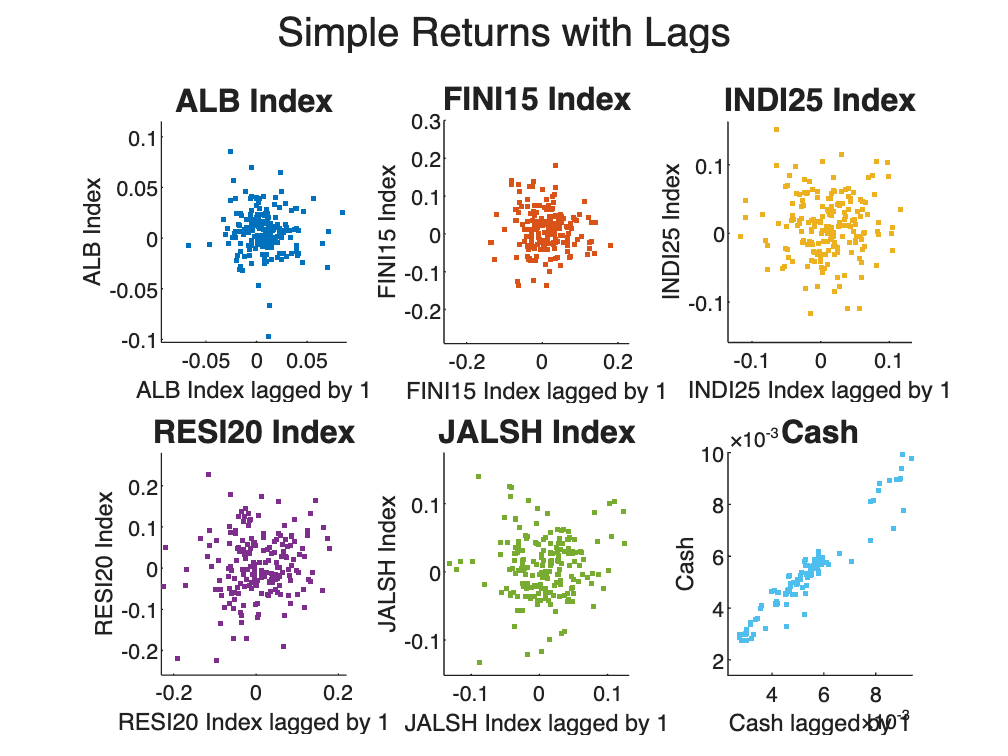

%Get the variable names 
varNames = M_Ret_TT.Properties.VariableNames;

% Create fig
figure;
% plot grid 
numRows = 2;
numCols = 3;

% Colour palette: Hexadecimal Colour Codes
colours = [0 0.4470 0.7410; % dark blue
          0.8500 0.3250 0.0980; % orange
          0.9290 0.6940 0.1250; % yellow
          0.4940 0.1840 0.5560; % purple
          0.4660 0.6740 0.1880; % green
          0.3010 0.7450 0.9330]; % light blue

% Loop over each variable
for i = 1:length(varNames)
    % Get the current and lagged version
    current_var = M_Ret_TT.(varNames{i});
    current_lag = lagmatrix(current_var, 2);
    
    % Create scatter plot of current_var and current_lag
    subplot(numRows, numCols, i);
    scatter(current_lag,current_var, '.', 'MarkerEdgeColor', colours(i,:), ...
        'MarkerFaceColor', colours(i,:));
    
    % Set the title & axis labels of subplots
    title(M_Ret_TT_PlotNames{i},'FontSize',12);
    ylabel(M_Ret_TT_PlotNames{i});
    xlabel(strcat(M_Ret_TT_PlotNames{i}, " lagged by 1"));

    % Make the x, y axes equal in length
    axis equal;
end
sgtitle("Simple Returns with Lags");
subplot(2,3,1)
xlim([-0.094 0.089])
ylim([-0.103 0.115])
subplot(2,3,2)
xlim([-0.26 0.23])
ylim([-0.29 0.30])
subplot(2,3,3)
xlim([-0.135 0.133])
ylim([-0.159 0.163])
subplot(2,3,4)
xlim([-0.23 0.22])
ylim([-0.26 0.28])
subplot(2,3,5)
xlim([-0.140 0.132])
ylim([-0.152 0.175])
subplot(2,3,6)
xlim([0.0023 0.0094])
ylim([0.0014 0.0100])
% Export the fig as a PDF
ASSETCL_Lag_Scatterplot = gcf;
hold off

#### **Export Returns Lag scatters Plot**

% exportName = 'ASSETCL_Lag_Scatterplot.pdf';
% exportgraphics(ASSETCL_Lag_Scatterplot, ...
%     fullfile(imageExportpath,exportName),'Resolution',300);

ARMA(1,1) model to see the p-values suggest a good fit

% Fit an ARMA model to the data
% p = 1; % AR order
% q = 1; % MA order
% armaModel = arima(p, 0, q);
% estimatedModel = estimate(armaModel, M_Ret_TT.FINI15_Index);
% 
% % Calculate the residuals
% [YF,YMSE] = forecast(estimatedModel,189,M_Ret_TT.FINI15_Index);
% residuals = M_Ret_TT.FINI15_Index - YF; % Change Forecast to predict if needed
% 
% % Plot the residuals to visualize their behavior
% figure;
% plot(residuals);
% title('Residuals of ARMA Model');
% xlabel('Time');
% ylabel('Residuals');

% qqplot(residuals)

# **TO DO at latter stage:**

To create subplots with contours we cant use subplot function. Need to use https://uk.mathworks.com/matlabcentral/answers/100920-how-do-i-put-a-scatterhist-plot-as-a-subplot-in-a-figure-in-matlab-7-5-r2007b

% % Get the variable names 
% varNames = BALFUN_log_diff.Properties.VariableNames;
% 
% % Create figure
% figure;
% % Set the number of rows and columns for subplots
% numRows = 3;
% numCols = 3;
% 
% % Colour palette: Hexadecimal Colour Codes
% colours = [0.3010 0.7450 0.9330; % blue
%           0.8500 0.3250 0.0980; % orange
%           0.9290 0.6940 0.1250; % yellow
%           0.4940 0.1840 0.5560; % purple
%           0.4660 0.6740 0.1880; % green
%           0.3010 0.7450 0.9330; % light blue
%           0.6350 0.0780 0.1840]; % red
% 
% % Loop over each variable
% for i = 1:length(varNames)
%     % Get the current and lagged version
%     current_var = BALFUN_log_diff.(varNames{i});
%     current_lag = lagmatrix(current_var, 1);
%     
%     % Create scatter histogram plot of current_var and current_lag
%     subplot(numRows, numCols, i);
%     scatterhist(current_lag, current_var, 'Marker', '.', 'Color', colours(i,:));
%     
%     % Set the title & axis labels of subplots
%     title(BALFUN_PlotNames{i});
%     ylabel(BALFUN_PlotNames{i});
%     xlabel(strcat(BALFUN_PlotNames{i}, " lagged by 1"));
%     
%     % Make the x, y axes equal in length
%     axis equal;
% end
% 
% % Export the figure as a PDF
% BALFUN_logDifRet_Lag_Scatterplot = gcf;
% hold off;
